# 機械学習を使用した人間の活動の分類

これは教師あり学習の例です。 

人間の活動センサー データには、6 つの異なる活動 (Walking、Sitting、Laying、Standing、Walking Upstairs、Walking Downstairs) を行っているときに人が装着しているスマートフォンから取得したセンサー測定から得られた観測値が含まれています。 

この例の目標は、センサー測定に基づいて活動タイプを自動的に識別できる分類子を構築することです。**この教師あり学習の例では、ラベル付けされたデータと機能を操作します。 **

**この例は、教師なし学習の例 (人間の活動のクラスタリング) に基づいており、このファイル単独では実行できません。 **

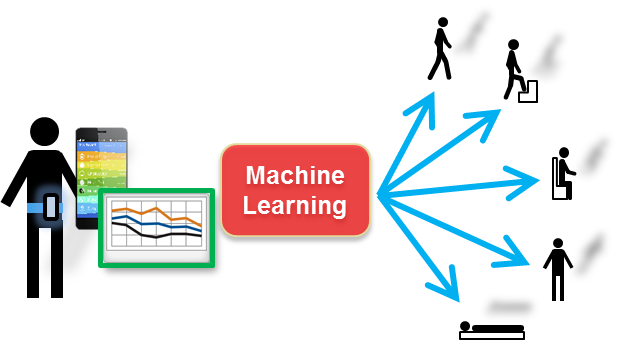

## トレーニング データとテスト データの調査

### トレーニング データ

前の演習では、トレーニング データを既に読み込みました。また、いくつかの機能 (平均、標準偏差) も抽出しました。 

トレーニング データの概要を見ると、アクティビティごとに約 1000 個のサンプルがあることがわかります。 

summary(trainActivity)

### テスト データ

トレーニング後にモデルを評価するために、テスト データ セットをモデルに渡します。テスト データ セットは、トレーニング データ セットと同じ形式である必要があります。したがって、トレーニング データで行ったのと同じ特徴を抽出する必要があります。そこで、トレーニング データと同じ手順を実行します。 

テスト データ セットには、2947 個のサンプルと、アクティビティごとに約 500 個のサンプルが含まれています。 

注: テスト データをロードすると、同じ名前を持つトレーニング データ変数 (t `otal_acc_x` など) が上書きされます。 

load('rawSensorData_test.mat')
summary(testActivity)
accX_mean = mean(total_acc_x, 2);
accY_mean = mean(total_acc_y, 2);
accZ_mean = mean(total_acc_z, 2);
gyroX_mean = mean(body_gyro_x, 2);
gyroY_mean = mean(body_gyro_y, 2);
gyroZ_mean = mean(body_gyro_z, 2);

accX_std = std(total_acc_x, [], 2);
accY_std = std(total_acc_y, [], 2);
accZ_std = std(total_acc_z, [], 2);
gyroX_std = std(body_gyro_x, [], 2);
gyroY_std = std(body_gyro_y, [], 2);
gyroZ_std = std(body_gyro_z, [], 2);

% 1 つの配列に結合します
ActivityDataTest = [accX_mean accY_mean accZ_mean accX_std accY_std accZ_std ...
    gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std];

% 変数をクリアします (ワークスペースをクリーンな状態に保つため)
clear accX_mean accY_mean accZ_mean accX_std accY_std accZ_std gyroX_mean gyroY_mean gyroZ_mean gyroX_std gyroY_std gyroZ_std

## モデルのトレーニング

 [分類学習アプリ](matlab: web(fullfile(docroot, 'stats/classificationlearner-app.html'))) を使用して、分類子を対話的にトレーニング、比較、および選択します。機械学習における最大の課題の 1 つは、同じ問題に適用できるさまざまな機械学習アルゴリズムがあり、どれが最適かを事前に知る方法がないことです。分類学習器アプリを使用すると、さまざまなモデリング手法をすばやく簡単に試すことができます。 

分類学習器アプリを開くには、以下のコマンドを実行するか、[アプリ] に移動して  をクリックします。 

classificationLearner 

ステップ 1: 新規セッション を開始し、[ワークスペースから] 変数を選択します

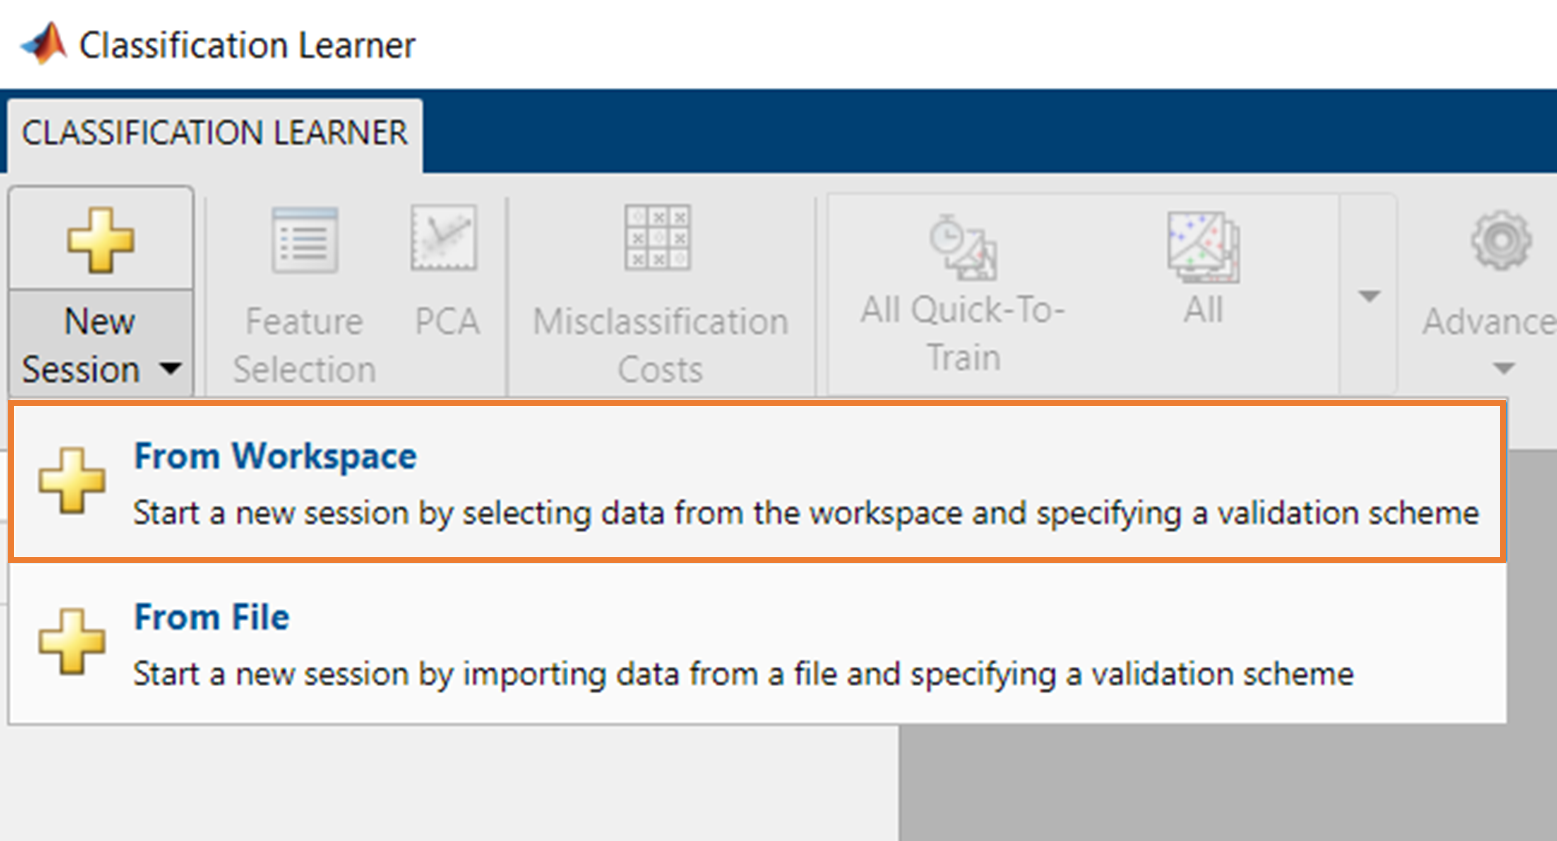

ワークスペースから `ActivityDataTrain` 変数を  ***データ セット変数 *** として選択します。 * 応答*変数 * を ****ワークスペース*****から** 選択し、 `trainActivity` を選択します。 **検証** セクションはそのままにして ( 交差検証 と 分割数 )、 **セッションの開始** をクリックします。 

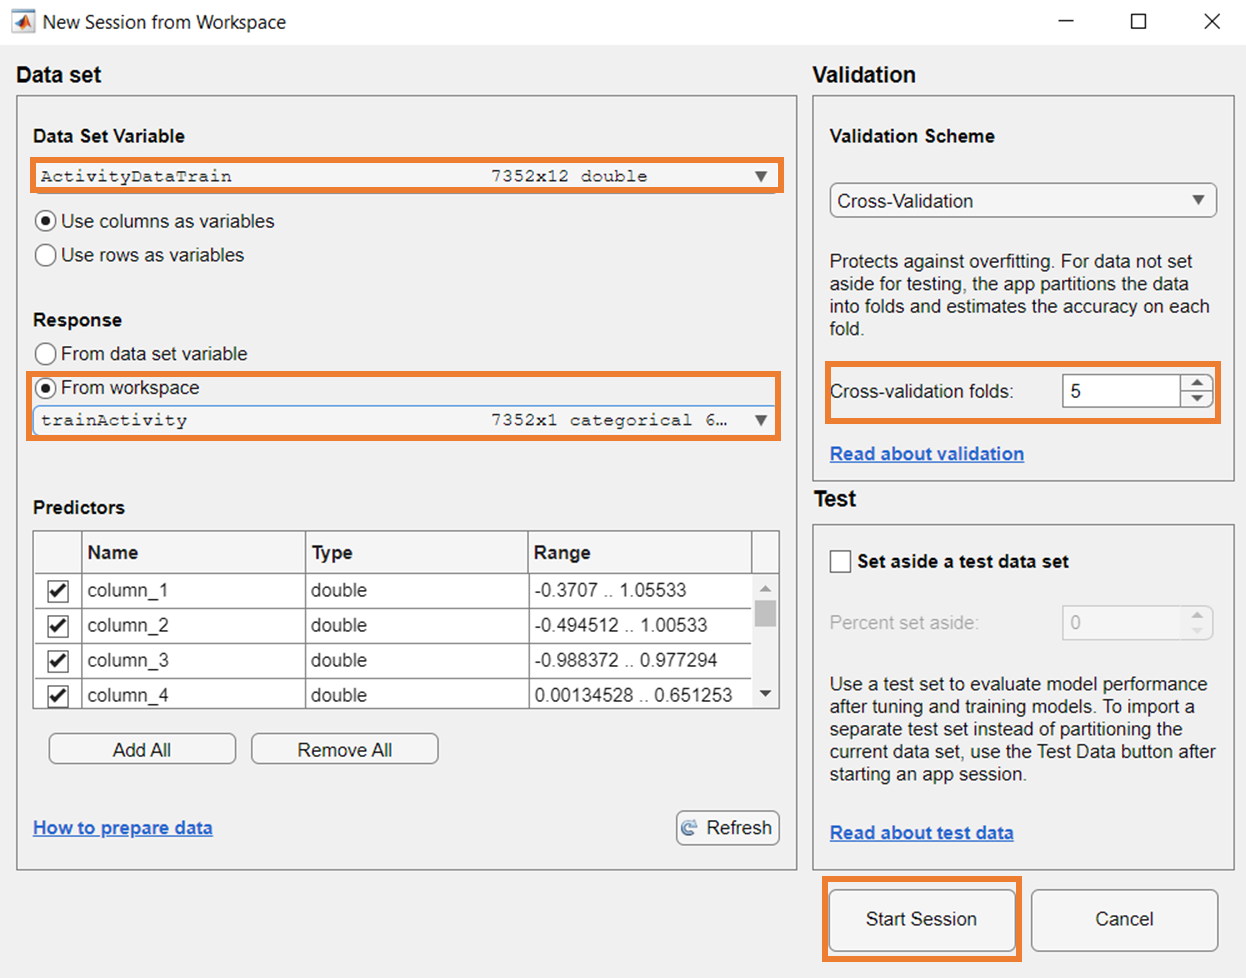

ステップ 2: **モデル** で **すべてのクイック学習** を選択し、**すべてを学習**  をクリックしてトレーニングを開始します。トレーニングには数秒しかかかりません。 

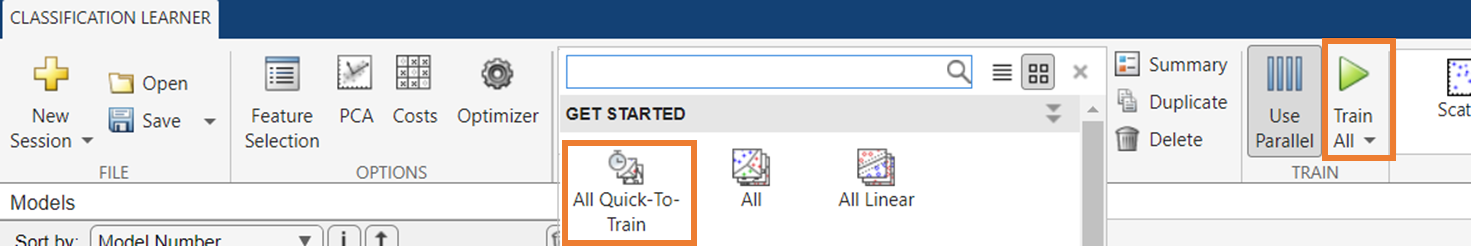

左のモデル ウィンドウに、トレーニングの進行状況が表示され、完了すると各モデルの最終的な (検証) 精度が表示されます。最も精度の高いものは太字で強調表示されます。結果は次のようになるはずです: 

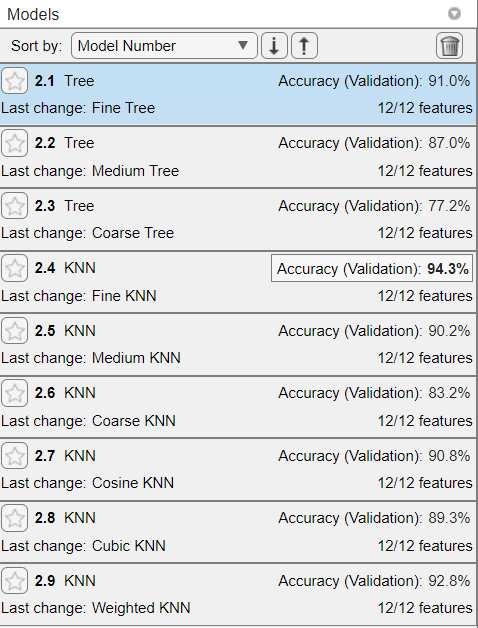

ステップ 3: 個々のモデルをクリックして各モデルの混同行列を調べます。

## トレーニング済みモデルの評価

未知のデータ (テスト データ) に対する各モデルのパフォーマンスを評価できます。 

**テスト データ** *ドロップダウン メニューをクリックし、****ワークスペースから**** を選択してテスト データ セットを読み込みます。 * **テスト データ セット変数** として `ActivityDataTest` を選択し (*応答の*変数が `testActivity` であることを確認してください)、**インポート** をクリックします。

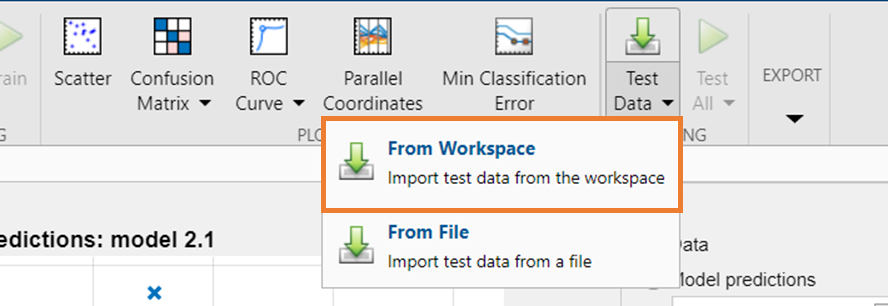

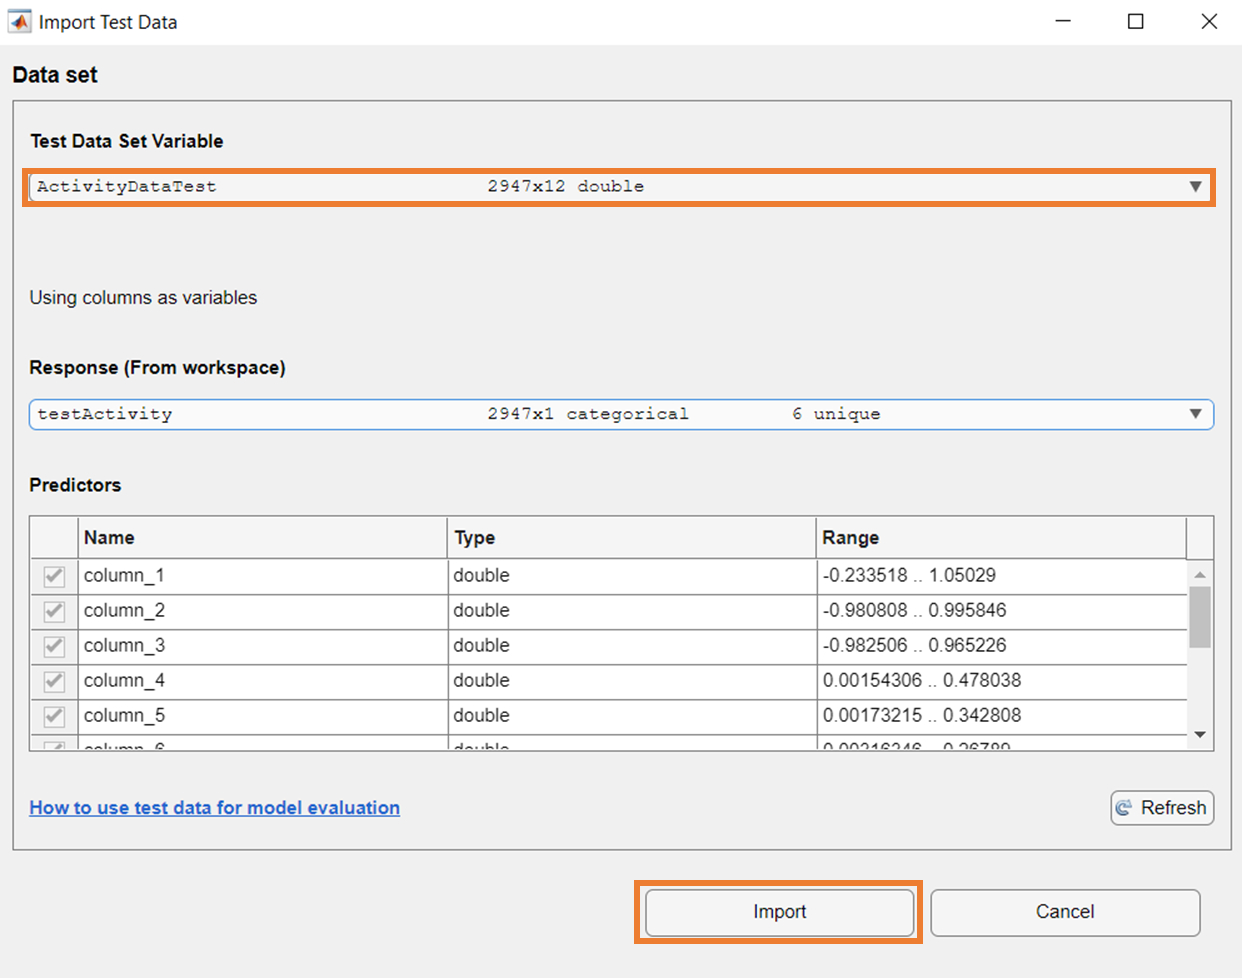

スター ボタン (*お気に入りに追加*) をクリックし、***選択項目をテスト***  をクリックして、パフォーマンスを評価するモデルを選択します。あるいは、モデルを選択せずに **すべてテスト **をクリックすると、モデル* ウィンドウ * の精度が ***精度*****(テスト)**  に変わります。結果は次のようになるはずです: 

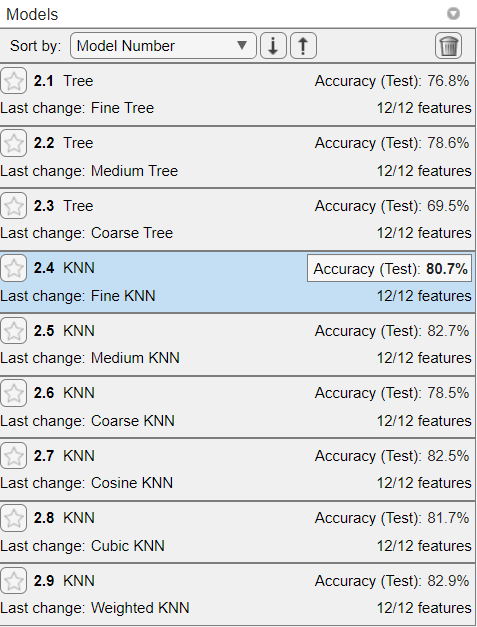

混同行列を使用して、テスト データでモデルが間違った場所を視覚化できます。 

## Export model

 `EXPORT` をクリックし、 * Export Model * を選択してモデルをエクスポートできます。必要に応じてモデルの名前を変更できます。トレーニング済みモデルがワークスペースに表示されます。 

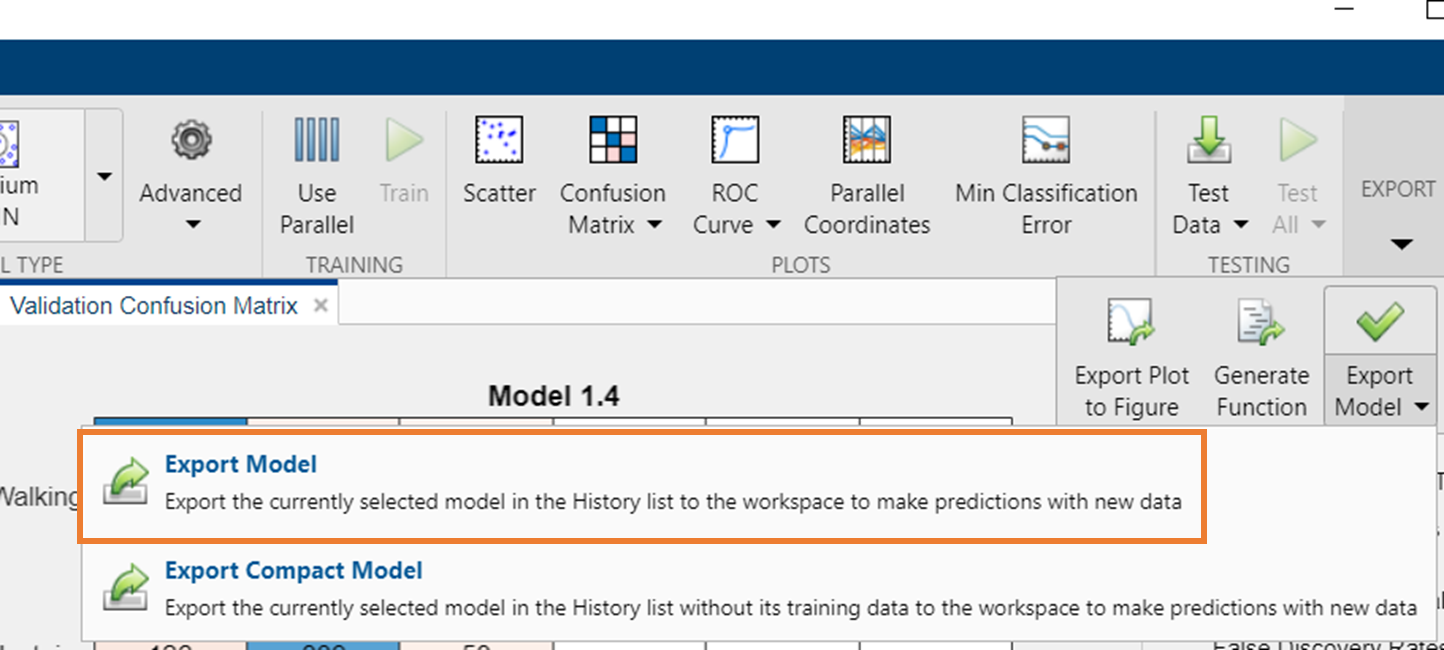

あるいは、 `Generate Function` をクリックして、後で使用するために関数を生成することもできます (関数を含む新しいウィンドウが開きます)。生成された関数は、以前に説明した手順をプログラムで実行する方法も示します。 

## まとめと次の手順

この例では、携帯電話から取得した人間の活動データを分類する機械学習モデルを構築しました。統計的尺度を適用して基本的な特徴を抽出し、分類学習アプリでいくつかのモデルを対話的にトレーニングして、パフォーマンスを比較しました。 

明らかに、この問題は十分に解決されておらず、最高のテスト精度はまだ約 81% です。精度を向上させるために試すことができる追加の手順は次のとおりです。  

- より優れた特徴: 信号処理の知識を活用することで、より強力な特徴を抽出できます。 [こちら](https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/submissions/54139/versions/2/previews/html/DataClumsing.html) 使用できる 1 つの例。 

- ハイパーパラメータの調整: 各モデルには、最適なパフォーマンスを実現するために適切に設定する必要があるパラメータがあります。 [こちら](https://www.mathworks.com/help/stats/hyperparameter-optimization-in-classification-learner-app.html) 分類学習アプリ内でハイパーパラメータを最適化する方法の例。 [こちら](https://www.mathworks.com/help/stats/bayesian-optimization-algorithm.html) は、ベイズ最適化の実行方法に関する詳細情報です。または、分類器のパフォーマンスを向上させるために、「 [fitcauto](matlab: web(fullfile(docroot, 'stats/fitcauto.html'))) 」関数を使用して、最適化されたハイパーパラメータを持つ分類モデルを自動的に選択することもできます。詳細については、AutoML [こちら](https://www.mathworks.com/discovery/automl.html) を参照してください。 

- ディープラーニングを試すことができます (HumanActivityClassification_DL.mlx を参照) 

*Copyright 2022, The MathWorks, Inc.*